clear all;
clc;

## 直角坐标机器人建立

L1=Link([pi,1500,0,pi/2]);
L1.jointtype='P'; % 滑动关节
L1.qlim=[100,5000]; % 关节1最大活动限度
L2=Link([-pi/2,1500,0,pi/2]);
L2.jointtype='P'; % 滑动关节
L2.qlim=[100,5000]; % 关节2最大活动限度
L3=Link([-pi/2,1500,0,pi/2]);
L3.jointtype='P'; % 滑动关节
L3.qlim=[100,5000]; % 关节3最大活动限度

## 刀头建模

刀头D-H参数

theta=[pi/2,3*pi/4,pi,pi/4,pi/2];
d=[0 0 -300/(sqrt(2)) 0 300 ];
a=[300 -300/sqrt(2) 0 -300 0];
alpha=[pi/2 pi/2 pi/2 pi/2 0];

刀头D-H参数和关节旋转限度

L4=Link([theta(1)    d(1)     a(1)     alpha(1)          ]);
L5=Link([theta(2)    d(2)     a(2)     alpha(2)          ]);
L5.qlim=[3*pi/4,3*pi/4];
L6=Link([theta(3)    d(3)     a(3)     alpha(3)          ]);
L7=Link([theta(4)    d(4)     a(4)     alpha(4)          ]);
L7.qlim=[-3*pi/4,-3*pi/4];
L8=Link([theta(5)    d(5)     a(5)     alpha(5)          ]);
L8.qlim=[pi/2,pi/2];

## 建立直角坐标水刀机器人

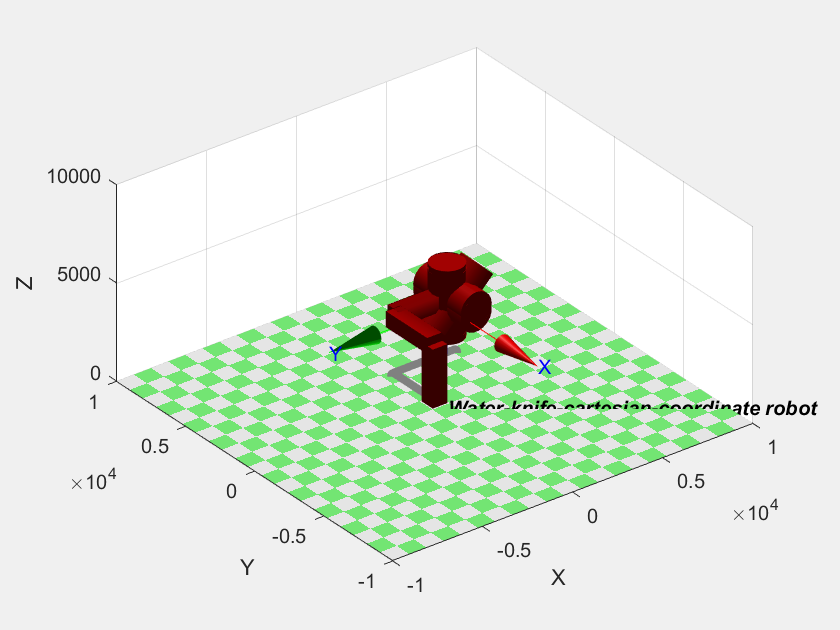

MyRobot=SerialLink([L1,L2,L3,L4,L5,L6,L7,L8] ,'name','Water-knife-cartesian-coordinate robot','base', transl(0,0,0)*trotz(0),'modified'); % 底座位置(0,0,0)
MyRobot.plot([3000,3000,3000,pi/2,3*pi/4,pi,pi/4,pi/2],'workspace',[-10000 10000 -10000 10000 0 10000]);

输入$delta$和$gamma$

% delta = input('Please input delta=');
% gamma = input('Please input gamma=');
delta=30;
gamma=30;

关节角度

theta=[CalBeta(delta,gamma),3*pi/4,CalTheta(delta,gamma),pi/4,pi/2];

直线起点终点

initpoint=[8000,8000,5400];
endpoint=[2000,2000,1400];

移动步长

step=50;

## 运动轨迹可视化

 

ans = 
   -0.9881   -0.0983    0.1182      7880
   -0.1181   -0.0068   -0.9930      7880
    0.0984   -0.9951   -0.0049      5320
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7760
   -0.1181   -0.0068   -0.9930      7760
    0.0984   -0.9951   -0.0049      5240
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7640
   -0.1181   -0.0068   -0.9930      7640
    0.0984   -0.9951   -0.0049      5160
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7520
   -0.1181   -0.0068   -0.9930      7520
    0.0984   -0.9951   -0.0049      5080
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7400
   -0.1181   -0.0068   -0.9930      7400
    0.0984   -0.9951   -0.0049      5000
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7280
   -0.1181   -0.0068   -0.9930      7280
    0.0984   -0.9951   -0.0049      4920
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7160
   -0.1181   -0.0068   -0.9930      7160
    0.0984   -0.9951   -0.0049      4840
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      7040
   -0.1181   -0.0068   -0.9930      7040
    0.0984   -0.9951   -0.0049      4760
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6920
   -0.1181   -0.0068   -0.9930      6920
    0.0984   -0.9951   -0.0049      4680
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6800
   -0.1181   -0.0068   -0.9930      6800
    0.0984   -0.9951   -0.0049      4600
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6680
   -0.1181   -0.0068   -0.9930      6680
    0.0984   -0.9951   -0.0049      4520
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6560
   -0.1181   -0.0068   -0.9930      6560
    0.0984   -0.9951   -0.0049      4440
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6440
   -0.1181   -0.0068   -0.9930      6440
    0.0984   -0.9951   -0.0049      4360
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6320
   -0.1181   -0.0068   -0.9930      6320
    0.0984   -0.9951   -0.0049      4280
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6200
   -0.1181   -0.0068   -0.9930      6200
    0.0984   -0.9951   -0.0049      4200
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      6080
   -0.1181   -0.0068   -0.9930      6080
    0.0984   -0.9951   -0.0049      4120
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5960
   -0.1181   -0.0068   -0.9930      5960
    0.0984   -0.9951   -0.0049      4040
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5840
   -0.1181   -0.0068   -0.9930      5840
    0.0984   -0.9951   -0.0049      3960
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5720
   -0.1181   -0.0068   -0.9930      5720
    0.0984   -0.9951   -0.0049      3880
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5600
   -0.1181   -0.0068   -0.9930      5600
    0.0984   -0.9951   -0.0049      3800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5480
   -0.1181   -0.0068   -0.9930      5480
    0.0984   -0.9951   -0.0049      3720
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5360
   -0.1181   -0.0068   -0.9930      5360
    0.0984   -0.9951   -0.0049      3640
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5240
   -0.1181   -0.0068   -0.9930      5240
    0.0984   -0.9951   -0.0049      3560
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5120
   -0.1181   -0.0068   -0.9930      5120
    0.0984   -0.9951   -0.0049      3480
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5000
   -0.1181   -0.0068   -0.9930      5000
    0.0984   -0.9951   -0.0049      3400
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4880
   -0.1181   -0.0068   -0.9930      4880
    0.0984   -0.9951   -0.0049      3320
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4760
   -0.1181   -0.0068   -0.9930      4760
    0.0984   -0.9951   -0.0049      3240
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4640
   -0.1181   -0.0068   -0.9930      4640
    0.0984   -0.9951   -0.0049      3160
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4520
   -0.1181   -0.0068   -0.9930      4520
    0.0984   -0.9951   -0.0049      3080
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4400
   -0.1181   -0.0068   -0.9930      4400
    0.0984   -0.9951   -0.0049      3000
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4280
   -0.1181   -0.0068   -0.9930      4280
    0.0984   -0.9951   -0.0049      2920
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4160
   -0.1181   -0.0068   -0.9930      4160
    0.0984   -0.9951   -0.0049      2840
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4040
   -0.1181   -0.0068   -0.9930      4040
    0.0984   -0.9951   -0.0049      2760
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3920
   -0.1181   -0.0068   -0.9930      3920
    0.0984   -0.9951   -0.0049      2680
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3800
   -0.1181   -0.0068   -0.9930      3800
    0.0984   -0.9951   -0.0049      2600
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3680
   -0.1181   -0.0068   -0.9930      3680
    0.0984   -0.9951   -0.0049      2520
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3560
   -0.1181   -0.0068   -0.9930      3560
    0.0984   -0.9951   -0.0049      2440
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3440
   -0.1181   -0.0068   -0.9930      3440
    0.0984   -0.9951   -0.0049      2360
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3320
   -0.1181   -0.0068   -0.9930      3320
    0.0984   -0.9951   -0.0049      2280
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3200
   -0.1181   -0.0068   -0.9930      3200
    0.0984   -0.9951   -0.0049      2200
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3080
   -0.1181   -0.0068   -0.9930      3080
    0.0984   -0.9951   -0.0049      2120
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2960
   -0.1181   -0.0068   -0.9930      2960
    0.0984   -0.9951   -0.0049      2040
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2840
   -0.1181   -0.0068   -0.9930      2840
    0.0984   -0.9951   -0.0049      1960
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2720
   -0.1181   -0.0068   -0.9930      2720
    0.0984   -0.9951   -0.0049      1880
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2600
   -0.1181   -0.0068   -0.9930      2600
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2480
   -0.1181   -0.0068   -0.9930      2480
    0.0984   -0.9951   -0.0049      1720
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2360
   -0.1181   -0.0068   -0.9930      2360
    0.0984   -0.9951   -0.0049      1640
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2240
   -0.1181   -0.0068   -0.9930      2240
    0.0984   -0.9951   -0.0049      1560
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2120
   -0.1181   -0.0068   -0.9930      2120
    0.0984   -0.9951   -0.0049      1480
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2000
   -0.1181   -0.0068   -0.9930      2000
    0.0984   -0.9951   -0.0049      1400
         0         0         0         1


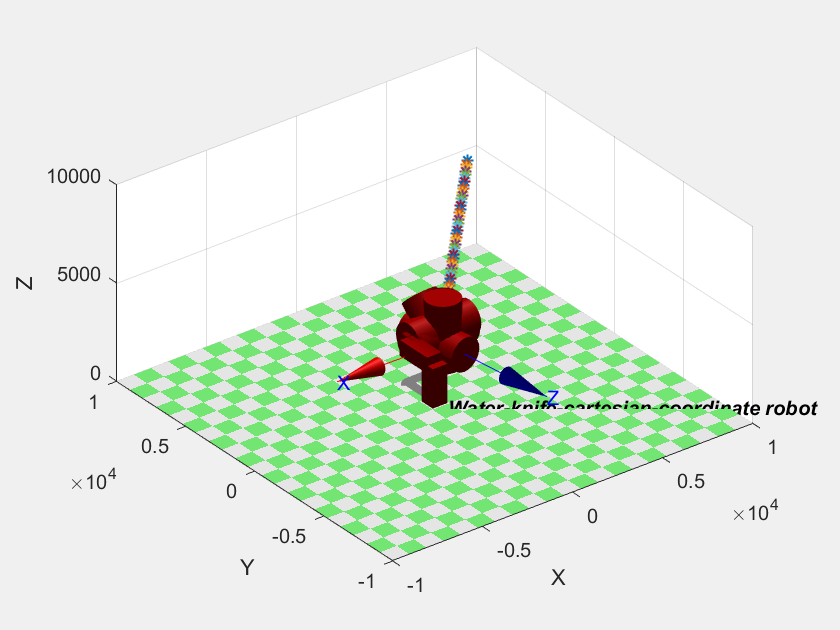

step_x=(endpoint(1)-initpoint(1))/step;
step_y=(endpoint(2)-initpoint(2))/step;
step_z=(endpoint(3)-initpoint(3))/step;

JointMat=[0,0,0,theta];
for i=1:step
    JointMat(1)=initpoint(3)+600+step_z*i;
    JointMat(2)=initpoint(2)+step_y*i;
    JointMat(3)=initpoint(1)+step_x*i;
    fkine(MyRobot,JointMat)
    hold on
    grid on
    plot3(initpoint(1)+step_x*i,initpoint(2)+step_y*i,initpoint(3)+600+step_z*i,'*','LineWidth',1);
    MyRobot.plot(JointMat);
end